# ***Client segmentation ***

## Goal

The goal is to segment the customers of a bank using Unsupervised Machine Learning techniques, this is a segmentation carried out from the perspective of the financial services sector.

#### Dataset loading

close all
clc
path = 'C:/Users/danie/Downloads/FINTECH/C) ML_LAB/LAB1/Zenti_BusinessCase1/BankClients.mat';
load(path)

### Data preparation 

Extraction of the variables of interest, also dividing into:

- numerical;

- categorical (excluding the ID, which is not informative at this level).

We have to:

- **encode** categorical variables, so that they can be digestible by clustering algorithms, they are all trasformed in boolean variables by the `dummyvar `function.

- **normalize** in [0, 1] numerical variables using the `rescale` function.

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; % create a matrix 
XNum = rescale(XNum); % normalize in [0, 1]

% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (ie create dummy variables)
%grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)]; % To use the dummy variables in a model, we must delete a column
end

Let's put all the features together in a matrix and start doing clustering analysis.

X = [XCat XNum];

We also save the original dataset without the encoding for a later simpler cluster inspection.

dati = Data;

### A short data exploration

#### Checking if there are highly correlater features

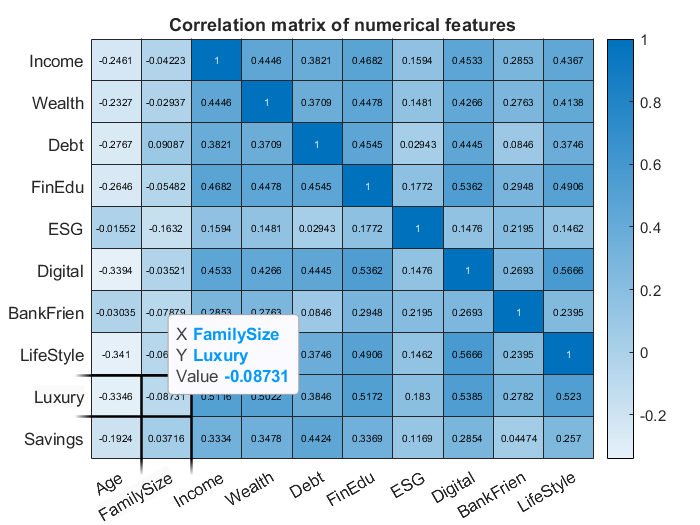

figure
R = corrcoef(XNum); %computation of the correlation matric
yvalues = {'Age','FamilySize','Income','Wealth','Debt','FinEdu','ESG','Digital','BankFrien','LifeStyle','Luxury','Savings'};
xvalues = {'Age','FamilySize','Income','Wealth','Debt','FinEdu','ESG','Digital','BankFrien','LifeStyle','Luxury','Savings'};
h = heatmap(xvalues,yvalues, R );
h.Title = 'Correlation matrix of numerical features';

There are no highly correlated features.

For quick exploratory/model selection analysis, we use a random subsample of the original dataset to avoid long-lasting computational times.

nSubSample = 1950;
rng('default') % for reproducibility
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);

dati = dati(randRows', :); %for cluster inspection 

## Unsupervised clustering with mixed categorical and continuous data

### Distance function

We use a created **custom distance metric** and function (MixDistance):

- for the categorical variables we use the **Hamming** **distance**, which is the percentage of coordinates that differ;

- for the numerical features we use the **L1 norm**[;](https://en.wikipedia.org/wiki/Taxicab_geometry);)

- we combine them using the relative weight of categorical/numerical variables.

We also try a variation of the previous distance metric that we call MixDistance1, instead of the manhattan norm, this distance function use the **Euclidean norm **for the numerical features.

### Hierarchical Clustering

The goal is to identify the unknown groups between the clients, we don't know how many groups could exist. Units that belong to the same cluster are more similar than units belonging to different clusters so we will use the two distance metrics defined before to "identify" dissimilarity/similarity between clients and we look to find homogeneous subgroups among the clients who might be more receptive to a particular form of advertising, or more likely to purchase a particular product.

With hierarchical clustering we specify first the distance metric, then we compute a distance matrix. We also have to specify how to measure the dissimilarities between clusters, the most used are single linkage, complete linkage, average linkage and centroid linkage.

Why hierarchical clustering? With hierarchical clustering we are referrinf to the fact that the clusters obtained by cutting the dendogram at a given height are necessary nested within the clusters obtained by cutting the dendogram at any greater height. So we are making a hierarchical structure assumption since, we are all different, but with some common features, so we could imagine a nested structure between clusters.

### Some Data Exploration

Let's have a bird’s view of the characteristics of the dataset and the behaviour of different distance metrics.

Let's compare distance metrics using **t-SNE**: an algorithm for dimensionality reduction that is well-suited to visualizing high-dimensional data. The underlying idea is to embed high-dimensional points in low dimensions in a way that respects similarities between points to see natural clusters in the original high-dimensional data, using specific distance metrics.

We begin with 2-D t-SNE embedding.

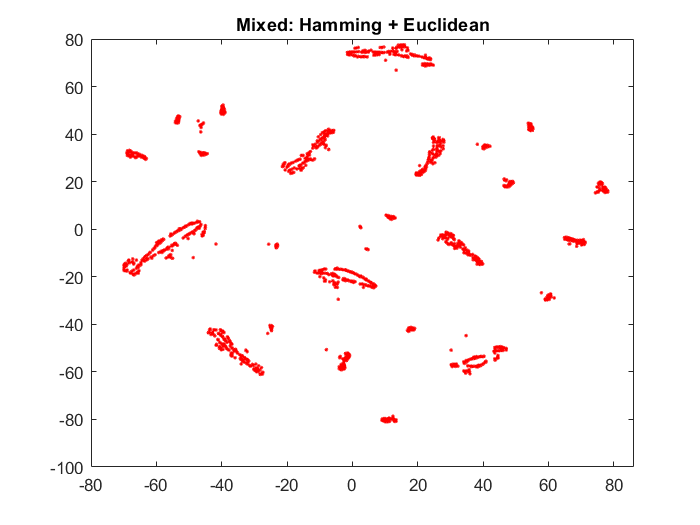

rng('default') % for reproducibility 9clu
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance1);
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Euclidean')

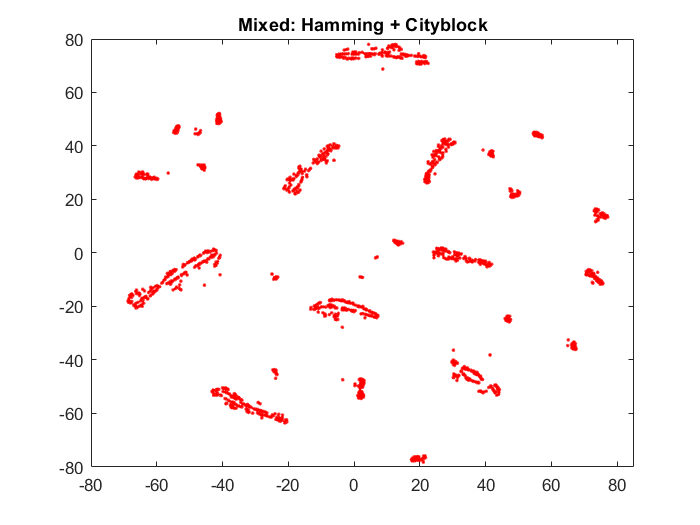


rng('default') % for fair comparison 9 cl
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance);
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Cityblock')

Now, Let's scale up and try a 3-D t-SNE embedding.

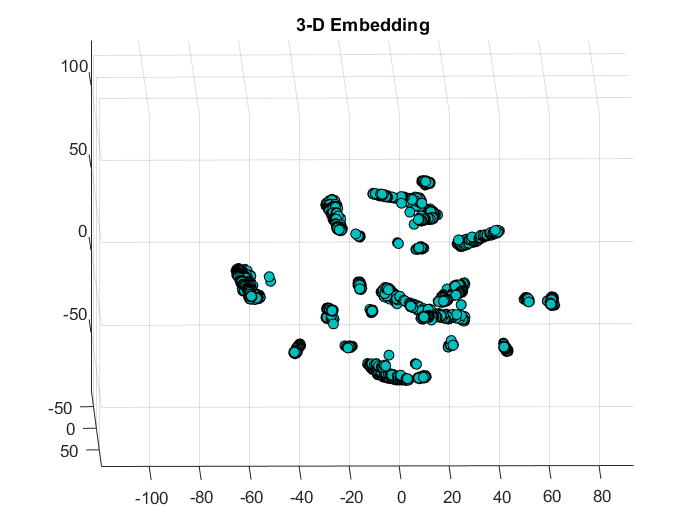

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance1,'NumDimensions',3);
figure
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D Embedding')
view(-30,15)

The t-SNE seems to produce around to 8/9 clusters, but the problem with t-SNE is that it does not preserve distances nor density, it preserves nearest-neighbors. The difference might appear subtle, but it affects any density or distance based algorithm:  we will never know for sure whether the "clusters" we found are real, or just artifacts of t-SNE. Anyway,  t-SNE with default settings usually does a good job of embedding the high-dimensional initial data into 2 or 3-dimensional points that have well defined clusters.

#### Similarity/dissimilarity matrix

We find the similarity between every pair of objects in the data set using the custom distance metric. 

D = pdist(X, @MixDistance);   %calculate the distance between every pair of objects in the dataset using MixDistance
D1 = pdist(X, @MixDistance1); %calculate the distance between every pair of objects in the dataset using MixDistance
squareform(D)                 %locate the distance between every pair of observations in a symmetric matrix

ans =          0    0.2525    1.9087    0.9606    1.8090    0.9443    1.9163    0.1717    0.2084    1.7825    1.7590    2.9144    1.8802    1.9738    0.3170    2.1322    2.6621    0.3111    1.7547    1.8748    1.9623    2.6544    4.3806    1.1175    1.9215    1.9159    2.7116    0.2920    1.9415    0.3064    4.2916    1.1376    1.9298    2.6182    1.9645    1.8408    1.7568    1.1422    2.9057    2.9239    1.9334    0.1813    3.4536    1.9531    1.0042    2.7071    2.6057    1.1131    1.2165    2.6532
    0.2525         0    3.0485    2.1880    2.8131    1.9794    1.9351    1.3092    1.0258    2.8887    2.8830    2.9619    3.1077    3.2164    1.0649    2.0898    3.9746    1.1481    2.9324    3.1975    2.8753    3.9614    4.6737    0.9693    3.1556    3.1500    2.8208    1.4492    2.9341    0.0794    5.5575    2.3838    2.9351    3.0388    2.0004    2.2042    2.9229    1.0909    2.9340    2.9593    3.2647    1.0066    4.6675    1.9859    1.9125    3.7010    3.9113    2.2662    1.1866   

#### Linkages

In this step we group the objects into a binary, hierarchical cluster tree. We link pairs of objects that are in close proximity using the [`linkage`](https://it.mathworks.com/help/stats/linkage.html) function. The `linkage` function uses the distance information generated in previous step to determine the proximity of objects to each other. As objects are paired into binary clusters, the newly formed clusters are grouped into larger clusters until a hierarchical tree is formed.

In the output of the linkage function , each row identifies a link between objects or clusters. The first two columns identify the objects that have been linked. The third column contains the distance between these objects.

single = linkage(D, "single");
complete = linkage(D, "complete");
average = linkage(D, "average");
weighted = linkage(D, "weighted");

ssss

single1 = linkage(D1, "single");
complete1 = linkage(D1, "complete");
average1 = linkage(D1, "average");
weighted1 = linkage(D1, "weighted");

#### **Dendrograms**

The hierarchical, binary cluster tree created by the `linkage` function is most easily understood when viewed graphically. The function [`dendrogram`](https://it.mathworks.com/help/stats/dendrogram.html) plots the tree as follows.

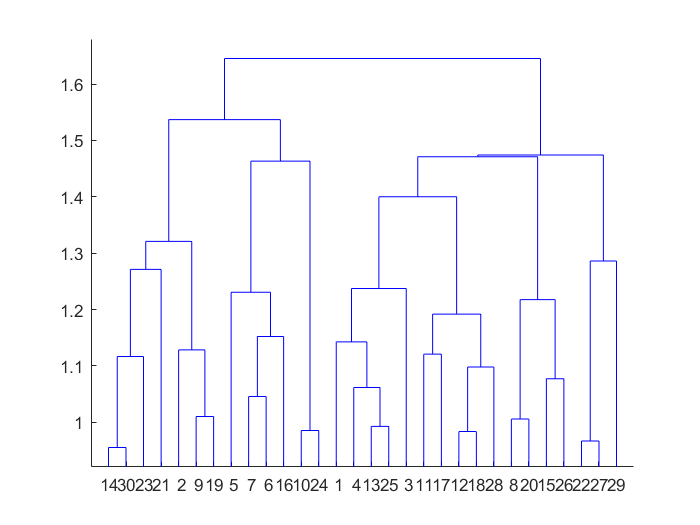

dendrogram(average1)

#### **Verify the Cluster Tree**

**Verify Dissimilarity**

In a hierarchical cluster tree, any two objects in the original data set are eventually linked together at some level. The height of the link represents the distance between the two clusters that contain those two objects. This height is known as the *cophenetic distance* between the two objects. One way to measure how well the cluster tree generated by the [`linkage`](https://it.mathworks.com/help/stats/linkage.html) function reflects your data is to compare the cophenetic distances with the original distance data generated by the [`pdist`](https://it.mathworks.com/help/stats/pdist.html) function. If the clustering is valid, the linking of objects in the cluster tree should have a strong correlation with the distances between objects in the distance vector. The [`cophenet`](https://it.mathworks.com/help/stats/cophenet.html) function compares these two sets of values and computes their correlation, returning a value called the *cophenetic correlation coefficient*. The closer the value of the cophenetic correlation coefficient is to 1, the more accurately the clustering solution reflects your data.

You can use the cophenetic correlation coefficient to compare the results of clustering the same data set using different distance calculation methods or clustering algorithms. For example, you can use the `cophenet` function to evaluate the clusters created for the sample data set.

c_single = cophenet(single,D)

c_single = 0.4840

c_single1 = cophenet(single1,D1)

c_single1 = 0.6539

c_average = cophenet(average,D)

c_average = 0.7188

c_average1 = cophenet(average1,D1)

c_average1 = 0.8090

c_complete = cophenet(complete,D)

c_complete = 0.6140

c_complete1 = cophenet(complete1,D1)

c_complete1 = 0.7362

c_weighted = cophenet(weighted,D)

c_weighted = 0.6783

c_weighted1 = cophenet(weighted1,D1)

c_weighted1 = 0.7851

**---------> best result obtained using euclidean and average linkage **

**Verify Consistency**

The relative consistency of each link in a hierarchical cluster tree can be quantified and expressed as the *inconsistency* *coefficient*. This value compares the height of a link in a cluster hierarchy with the average height of links below it. Links that join distinct clusters have a high inconsistency coefficient; links that join indistinct clusters have a low inconsistency coefficient.

To generate a listing of the inconsistency coefficient for each link in the cluster tree, use the [`inconsistent`](https://it.mathworks.com/help/stats/inconsistent.html) function. By default, the `inconsistent` function compares each link in the cluster hierarchy with adjacent links that are less than two levels below it in the cluster hierarchy. This is called the *depth* of the comparison. You can also specify other depths. The objects at the bottom of the cluster tree, called leaf nodes, that have no further objects below them, have an inconsistency coefficient of zero. Clusters that join two leaves also have a zero inconsistency coefficient.

I = inconsistent(average)

I =     0.0057         0    1.0000         0
    0.0066         0    1.0000         0
    0.0072         0    1.0000         0
    0.0082         0    1.0000         0
    0.0076    0.0015    2.0000    0.7071
    0.0087         0    1.0000         0
    0.0089         0    1.0000         0
    0.0091         0    1.0000         0
    0.0092         0    1.0000         0
    0.0092         0    1.0000         0


## **Create Clusters**

**5 clusters**

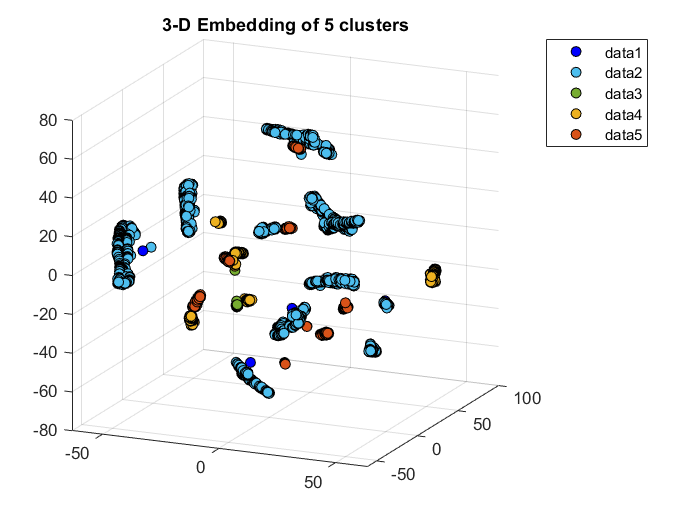

%T = cluster(Z,'cutoff',1.2)
T5 = cluster(average1,'maxclust',5);

figure
scatter3(Y(T5==1,1),Y(T5==1,2),Y(T5==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(T5==2,1),Y(T5==2,2),Y(T5==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(T5==3,1),Y(T5==3,2),Y(T5==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(T5==4,1),Y(T5==4,2),Y(T5==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(T5==5,1),Y(T5==5,2),Y(T5==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
title('3-D Embedding of 5 clusters')
hold off
legend

**6 clusters**

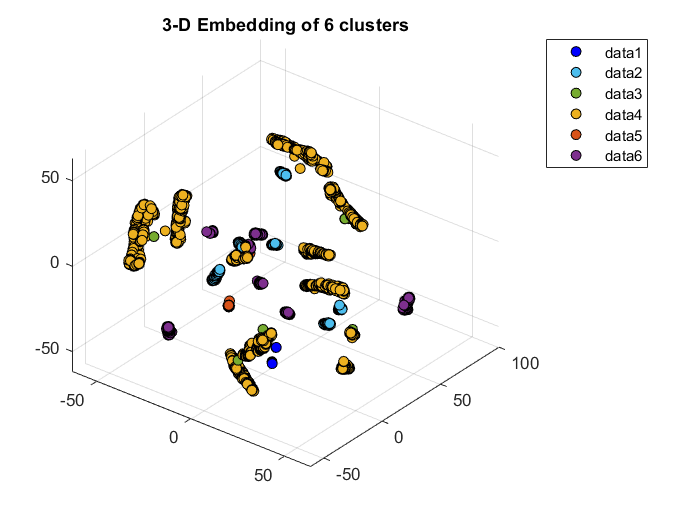

T6 = cluster(average1,'maxclust',6);

figure
scatter3(Y(T6==1,1),Y(T6==1,2),Y(T6==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(T6==2,1),Y(T6==2,2),Y(T6==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(T6==3,1),Y(T6==3,2),Y(T6==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(T6==4,1),Y(T6==4,2),Y(T6==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(T6==5,1),Y(T6==5,2),Y(T6==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(T6==6,1),Y(T6==6,2),Y(T6==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
title('3-D Embedding of 6 clusters')
legend
hold off

**7 clusters**

T7 = cluster(average1,'maxclust',7);

**8 clusters**

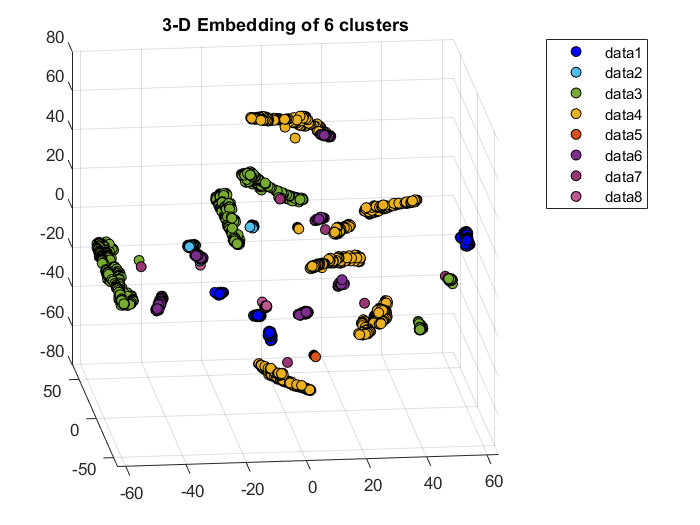

T8 = cluster(average1,'maxclust',8);

figure
scatter3(Y(T8==1,1),Y(T8==1,2),Y(T8==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(T8==2,1),Y(T8==2,2),Y(T8==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(T8==3,1),Y(T8==3,2),Y(T8==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(T8==4,1),Y(T8==4,2),Y(T8==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(T8==5,1),Y(T8==5,2),Y(T8==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(T8==6,1),Y(T8==6,2),Y(T8==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
scatter3(Y(T8==7,1),Y(T8==7,2),Y(T8==7,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.5940 0.220 0.4560])
scatter3(Y(T8==8,1),Y(T8==8,2),Y(T8==8,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.740 0.340 0.5560])
title('3-D Embedding of 6 clusters')
legend
hold off

**9 clusters**

T9 = cluster(average1,'maxclust',9);


#### Clustering evaluation

Our goal is to determine how well the data fits into a particular number of clusters using different evaluation criteria.

**Calinski-Harabasz criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.calinskiharabaszevaluation-class.html)](https://it.mathworks.com/help/stats/clustering.evaluation.calinskiharabaszevaluation-class.html)).

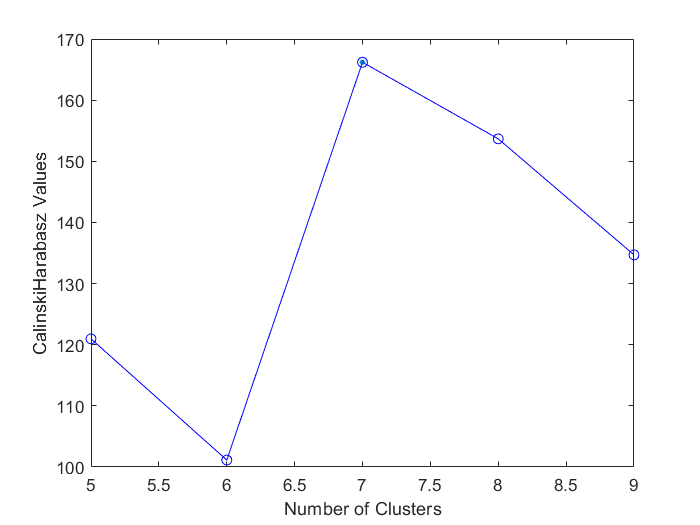

clust = [T5 T6 T7 T8 T9];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)

eva1

eva1 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 1950
         InspectedK: [5 6 7 8 9]
    CriterionValues: [120.9610 101.1383 166.1944 153.6701 134.6951]
           OptimalK: 7


**Davies-Bouldin criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.daviesbouldinevaluation-class.html](https://it.mathworks.com/help/stats/clustering.evaluation.daviesbouldinevaluation-class.html)).

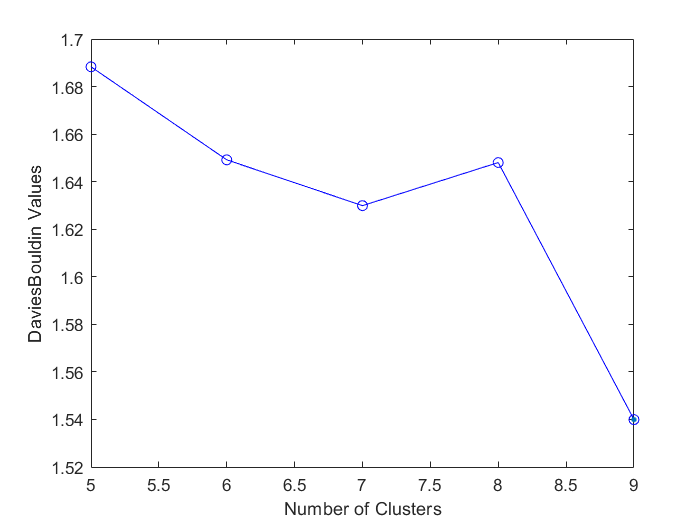

eva2 = evalclusters(X,clust,'DaviesBouldin');
figure
plot(eva2)

eva2

eva2 =   DaviesBouldinEvaluation with properties:

    NumObservations: 1950
         InspectedK: [5 6 7 8 9]
    CriterionValues: [1.6883 1.6492 1.6299 1.6480 1.5399]
           OptimalK: 9


**Silhouette criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html](https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html)).

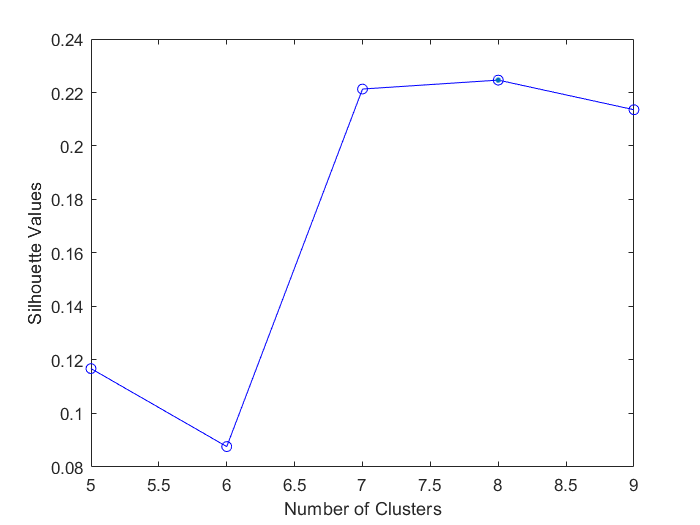

eva3 = evalclusters(X,clust,'silhouette', 'Distance', @MixDistance1);
figure
plot(eva3)

eva3

eva3 =   SilhouetteEvaluation with properties:

    NumObservations: 1950
         InspectedK: [5 6 7 8 9]
    CriterionValues: [0.1168 0.0876 0.2213 0.2246 0.2136]
           OptimalK: 8


Let's have a closer look at the silhouette of the most reasonable clusters hypothesis.

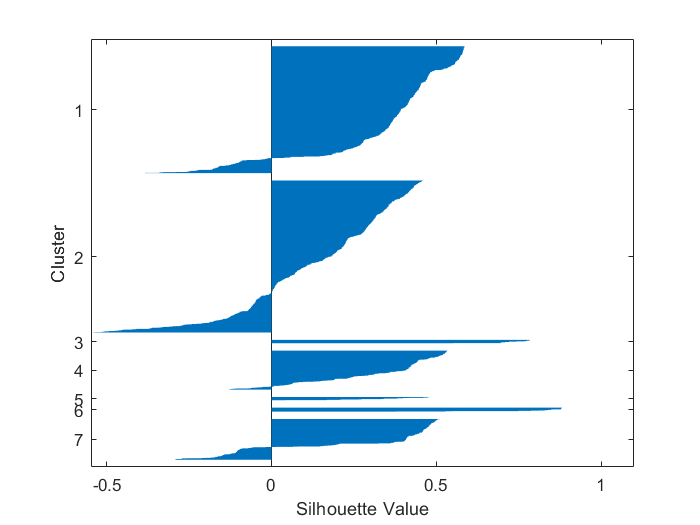

figure
silhouette(X,T7, @MixDistance);

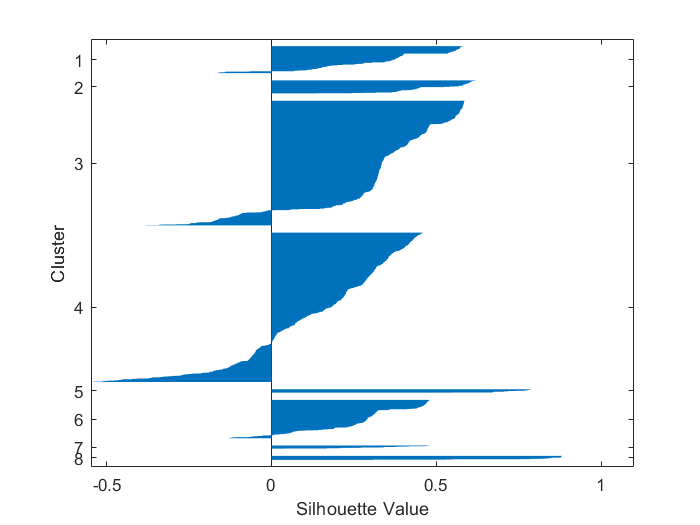

figure
silhouette(X,T8,@MixDistance);

There are 3 small clusters 

tabulate(T7)

  Value    Count   Percent
      1      670     34.36%
      2      803     41.18%
      3       18      0.92%
      4      206     10.56%
      5       17      0.87%
      6       21      1.08%
      7      215     11.03%


grpstats(X(:, 1), T7, 'numel')

### Cluster evaluation 

tabulate(dati.Gender(T7==3))

  Value    Count   Percent
      0        7     38.89%
      1       11     61.11%


tabulate(dati.Job(T7==3))

  Value    Count   Percent
      1        0      0.00%
      2       18    100.00%
      3        0      0.00%
      4        0      0.00%
      5        0      0.00%


tabulate(dati.Area(T7==3))

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3       18    100.00%


tabulate(dati.CitySize(T7==3))

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3       18    100.00%


tabulate(dati.Investments(T7==3))

  Value    Count   Percent
      1        0      0.00%
      2        7     38.89%
      3       11     61.11%


X1= array2table(X);
summary(X1(T7==3, 17))

Variables:

    X17: 18×1 double

        Values:

            Min       0.0030694
            Median    0.0064614
            Max        0.009607



summary(XX(T7==3, "Digital"))

Unrecognized function or variable 'XX'.

statarray = grpstats(dati.BankFriend,T7)

statarray =     0.6216
    0.6367
    0.6860
    0.5840
    0.5573
    0.5746
    0.6372


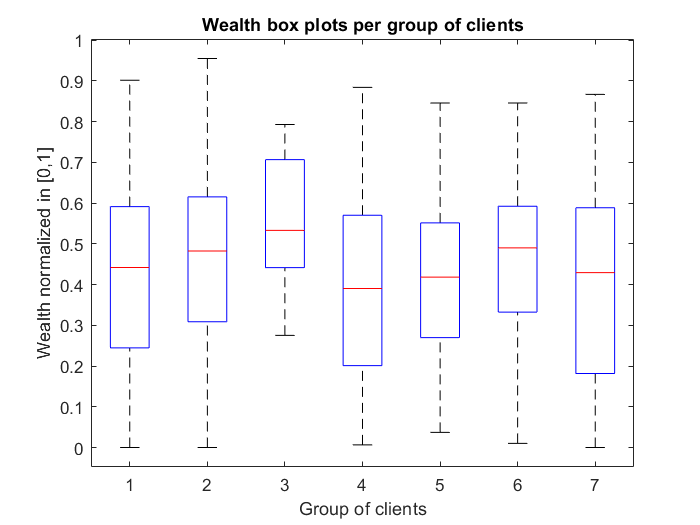

boxplot(dati.Debt, T7)
title('Wealth box plots per group of clients')
xlabel('Group of clients')
ylabel('Wealth normalized in [0,1]')

boxplot(dati.Debt, T7)
title('Wealth box plots per group of clients')
xlabel('Group of clients')
ylabel('Wealth normalized in [0,1]')

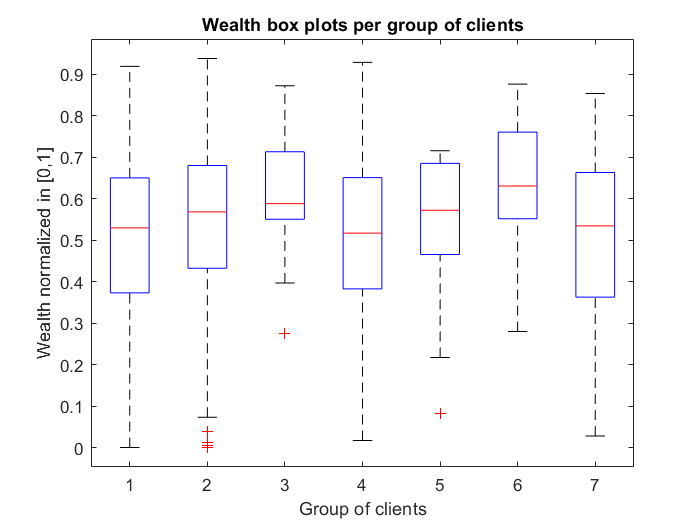

boxplot(dati.Saving, T7)
title('Wealth box plots per group of clients')
xlabel('Group of clients')
ylabel('Wealth normalized in [0,1]')

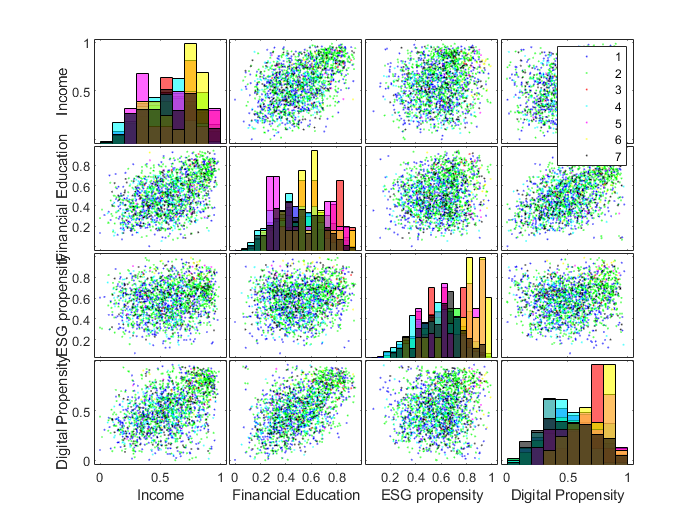

Data4Plot = [dati.Income  dati.FinEdu  dati.ESG  dati.Digital];
xnames = {'Income', 'Financial Education', 'ESG propensity', 'Digital Propensity'};
gplotmatrix(Data4Plot,[],T7, [],[],[],[],'grpbars', xnames)